# Global

mu_0 = 4*pi*10^(-7)

mu_0 = 1.2566e-06

l_11 = 0.13

l_11 = 0.1300

l_12 = 0.075

l_12 = 0.0750

N_1 = 150

N_1 = 150

N_2 = 150

N_2 = 150

N_3 = 150

N_3 = 150

S_1 = 1.24e-4

S_1 = 1.2400e-04

S_2 = 1.20e-4

S_2 = 1.2000e-04


N = 2000

N = 2000

l_2 = 0.24

l_2 = 0.2400

l_g = 2e-3

l_g = 0.0020

## 1.1

% u_R1 即为 x
% u_C 即为 y
% 注意换算电压单位！！（乘 10^(-3)）


R_1 = 2

R_1 = 2

R_2 = 50e3

R_2 = 50000

C = 10e-6

C = 1.0000e-05


N_1/(l_11*R_1)

ans = 576.9231

R_2*C/(N_2*S_1)

ans = 26.8817

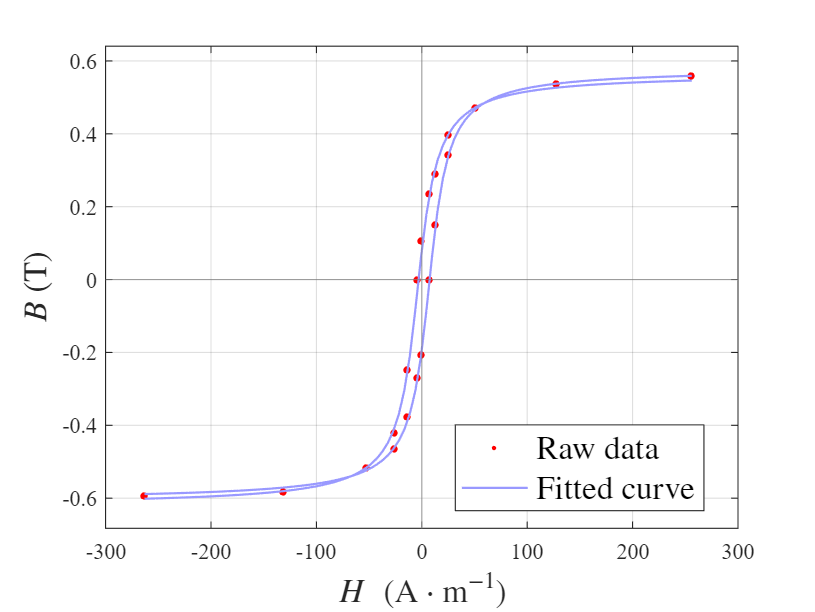


u_R1_array = 10^(-3)*[  % 横坐标
-456
-228
-91.2
-45.6
-22.8
-6.60
0.00
13.2
22.2
44.4
88.8
222
444
]';

u_C1_array = 10^(-3)*[  % 纵坐标（上半支）
-22.0
-21.6
-19.2
-15.6
-9.20
0.00
4.00
8.80
10.8
14.8
17.6
20.0
20.8
]';

u_C2_array = 10^(-3)*[  % 纵坐标（下半支）
-22.0
-21.6
-19.2
-17.2
-14.0
-10.0
-7.60
0.00
5.60
12.8
17.6
20.0
20.8
]';

H = N_1/(l_11*R_1) * u_R1_array;
B_1 = R_2*C/(N_2*S_1) * u_C1_array;
B_2 = R_2*C/(N_2*S_1) * u_C2_array;

% 用函数 y = y(x) = a*arctan(b*x + c) + d 来拟合磁滞回线的半支

fit1 = Ex_8_HysteresisLoopFitting(H, B_1);
fit2 = Ex_8_HysteresisLoopFitting(H, B_2);

figure('Color', [1 1 1])
ax = axes;
sca = MyScatter_ax(ax, [H, H(end:-1:1)], [B_1, B_2(end:-1:1)]);
sca.scatter.scatter_1.SizeData = 100;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';

x_array = linspace(H(1), H(end), 100);
p1 = MyPlot_ax(ax, x_array, fit1(x_array)');
p2 = MyPlot_ax(ax, x_array, fit2(x_array)');
xline(0, 'Color', [0.5, 0.5, 0.5])
yline(0, 'Color', [0.5, 0.5, 0.5])

p1.plot.plot_1.LineWidth = 1;
p2.plot.plot_1.LineWidth = 1;
p1.label.x.String = '$H\ \mathrm{(A\cdot m^{-1})}$ ';
p1.label.y.String = '$B$ (T)';
p1.leg.String = ["Raw data"; "Fitted curve"];


%MyExport_pdf

%ax2 = ax;
%xlim(ax2, [-70, 70])
%MyExport_pdf

B_r = (fit1(0) - fit2(0))/2;
H_c = (fzero(@(x) fit2(x), 0) - fzero(fit1, 0))/2;

disp(['B_r = ', num2str(B_r)])

B_r = 0.13707


disp(['H_c = ', num2str(H_c)])

H_c = 5.2434



%MyPrint_xlsx([H', B_1', B_2'], 3)
MyPrint_xlsx([u_R1_array', u_C1_array', u_C2_array'], 3)

ans = 13×3 cell 数组
    {'-0.456'}    {'-0.022'}    {'-0.022'}
    {'-0.228'}    {'-0.022'}    {'-0.022'}
    {'-0.091'}    {'-0.019'}    {'-0.019'}
    {'-0.046'}    {'-0.016'}    {'-0.017'}
    {'-0.023'}    {'-0.009'}    {'-0.014'}
    {'-0.007'}    {'0.000' }    {'-0.010'}
    {'0.000' }    {'0.004' }    {'-0.008'}
    {'0.013' }    {'0.009' }    {'0.000' }
    {'0.022' }    {'0.011' }    {'0.006' }
    {'0.044' }    {'0.015' }    {'0.013' }
    {'0.089' }    {'0.018' }    {'0.018' }
    {'0.222' }    {'0.020' }    {'0.020' }
    {'0.444' }    {'0.021' }    {'0.021' }


B_r = 26.8817 * [5.8, 4.4] * 10^(-3)

B_r =     0.1559    0.1183


H_c = 576.9231 * [10.2, 7.6] * 10^(-3)

H_c =     5.8846    4.3846


## 1.2

R_1 = 2

R_1 = 2

R_2 = 50e3

R_2 = 50000

C = 10e-6

C = 1.0000e-05


Delta_u_R1_array = [
5.76	7.00	7.68	10.2	12.9	15.9	17.80	24.8	31.6	42.4 ...
54.4	61.6	68.0	74.4	85.6	93.6	110	137	158	1070
]*10^(-3);

Delta_u_C_array = [
1.92	2.48	2.64	3.60	4.72	5.92	6.96	9.84	13.0	17.2 ...
21.2	23.2	25.2	26.4	28.8	30.4	32.4	34.4	36.0	42.4
]*10^(-3);

N_1/(l_11*R_1)*0.5

ans = 288.4615

R_2*C/(N_2*S_1)*0.5

ans = 13.4409

1/mu_0

ans = 7.9577e+05

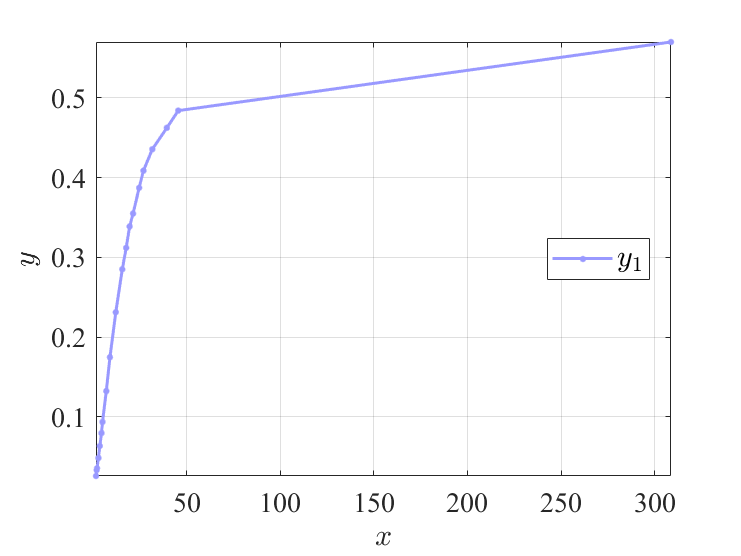

ans = 包含以下字段的 struct :
      fig: [1×1 Figure]
     axes: [1×1 Axes]
     plot: [1×1 struct]
    label: [1×1 struct]
      leg: [1×1 Legend]



H_m = N_1/(l_11*R_1)*0.5 * Delta_u_R1_array;
B_m = R_2*C/(N_2*S_1)*0.5 * Delta_u_C_array;
mu_m = 1/mu_0 * B_m./H_m;


MyPlot(H_m, B_m)

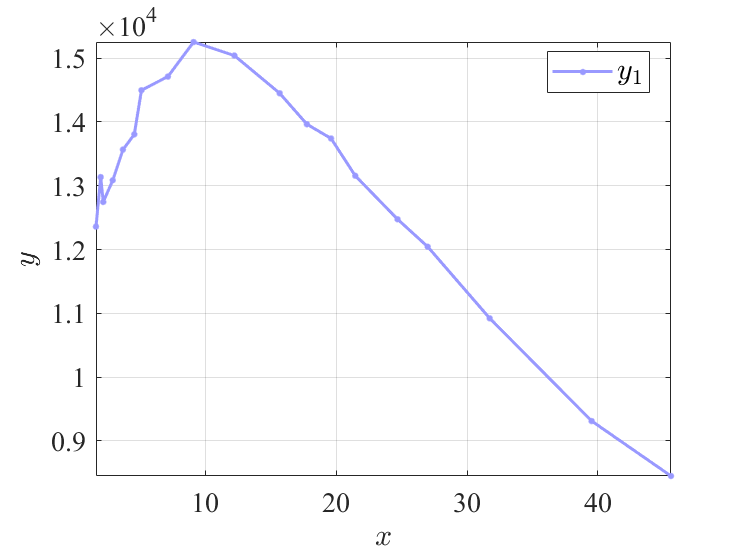

ans = 包含以下字段的 struct :
      fig: [1×1 Figure]
     axes: [1×1 Axes]
     plot: [1×1 struct]
    label: [1×1 struct]
      leg: [1×1 Legend]


MyPlot(H_m(1:end-1), mu_m(1:end-1))

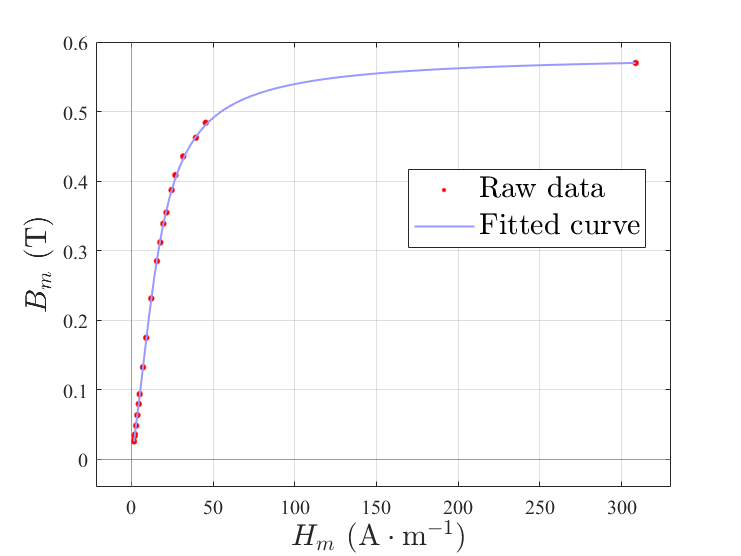


% 拟合
fit = Ex_8_HysteresisLoopFitting(H_m, B_m);

figure('Color', [1 1 1])
ax = axes;
sca = MyScatter_ax(ax, H_m, B_m);
sca.scatter.scatter_1.SizeData = 100;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';

x_array = linspace(H_m(1), H_m(end), 100);
p1 = MyPlot_ax(ax, x_array, fit(x_array)');
xline(0, 'Color', [0.5, 0.5, 0.5])
yline(0, 'Color', [0.5, 0.5, 0.5])

p1.plot.plot_1.LineWidth = 1;
p2.plot.plot_1.LineWidth = 1;
p1.label.x.String = '$H_m\ \mathrm{(A\cdot m^{-1})}$ ';
p1.label.y.String = '$B_m$ (T)';
p1.leg.String = ["Raw data"; "Fitted curve"];

0.13707/26.8817*1000

ans = 5.0990

5.2432/576.9231*1000

ans = 9.0882

## 1.3


N_1/(l_12*R_1)

ans = 1000

R_2*C/(N_2*S_2)

ans = 27.7778

ans = 0.0278


B = 27.7777777777* 33.6*10^(-3)

B = 0.9333

B = 27.7777777777* [20.8 23.2 24.0]*10^(-3)

B =     0.5778    0.6444    0.6667


## 1.4

R_1 = 2

R_1 = 2

R_2 = 20e3

R_2 = 20000

C = 2e-6

C = 2.0000e-06


N_1/(l_11*R_1)

ans = 576.9231

R_2*C/(N_2*S_1)

ans = 2.1505


h = N_3/l_11

h = 1.1538e+03

m = R_1*R_2*C*l_11/(mu_0*N_1*N_2*S_1)

m = 2.9663e+03

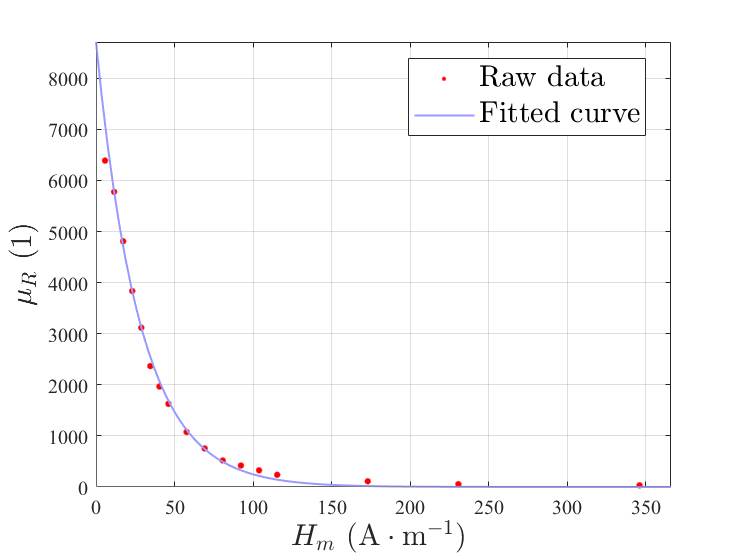


I = [
0.005	0.01	0.015	0.02	0.025	0.03	0.035	0.04 ...
0.05	0.06	0.07	0.08	0.09	0.10	0.15	0.2	0.3
];

Delta_u_R_1 = [
2.60	7.60	7.40	11.6	11.6	18.8	18.4	24.8 ...
20.4	22.8	24.0	24.0	23.6	37.2	36.8	124	124
];

Delta_u_C = [
5.60	14.8	12.0	15.0	12.2	15.0	12.2	13.6 ...
7.40	5.80	4.20	3.40	2.60	3.00	1.40	2.40	1.40
];

H = h*I;
mu_R = m* Delta_u_C./Delta_u_R_1;

%MyPlot(H, mu_R)

% 拟合 mu_R
fit_mu_R = Fit_mu_R(H, mu_R);

figure('Color', [1 1 1])
ax = axes;
sca = MyScatter_ax(ax, H, mu_R);
sca.scatter.scatter_1.SizeData = 100;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';

x_array = linspace(0, H(end)+20, 100);
p1 = MyPlot_ax(ax, x_array, fit_mu_R(x_array)');
xline(0, 'Color', [0.5, 0.5, 0.5])
yline(0, 'Color', [0.5, 0.5, 0.5])

p1.plot.plot_1.LineWidth = 1;
p2.plot.plot_1.LineWidth = 1;
p1.label.x.String = '$H_m\ \mathrm{(A\cdot m^{-1})}$ ';
p1.label.y.String = '$\mu_R$ (1)';
p1.leg.String = ["Raw data"; "Fitted curve"];


%MyExport_pdf

%MyPrint_xlsx([H', mu_R'], 3)

## 2.1

h = N/l_2

函数或变量 'N' 无法识别。

b = l_g/(mu_0*l_2)

I = [
0	54.4	102.7	147.9	194.3	242.9	300.9 ...
346.2	398.0	452.5	498.1	543.9	596.8	642.2    
]*10^(-3);

B = [
3.2	7.7	12.3	17.3	23.2	30.6	45.1	56.8 ...
69.4	82.1	92.3	101.9	111.7	119.1
]*10^(-3);

H = h*I
H_re = h*I - b*B

stc = MyPlot(H, B)
stc2 = MyPlot_ax(stc.axes, H_re, B)
MyColors = GetMyColors;
stc.plot.plot_1.LineStyle = "--";
stc2.plot.plot_1.Color = MyColors{2}

stc.label.x.String = '$H\ \mathrm{(A\cdot m^{-1})}$ ';
stc.label.y.String = '$B$ (T)';
stc.leg.String = ["Raw $H$"; "Revised $H$"];

%MyExport_pdf_docked
%MyPrint_xlsx([H', H_re'], 3)
fit_H_re = Fit_HAndB(H_re, B)

figure('Color', [1 1 1])
ax = axes;
sca = MyScatter_ax(ax, H_re, B);
sca.scatter.scatter_1.SizeData = 100;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';

x_array = linspace(0, H_re(end)+20, 100);
p1 = MyPlot_ax(ax, x_array, fit_H_re(x_array)');
xline(0, 'Color', [0.5, 0.5, 0.5])
yline(0, 'Color', [0.5, 0.5, 0.5])

p1.plot.plot_1.LineWidth = 1;
p2.plot.plot_1.LineWidth = 1;
p1.label.x.String = '$H_m\ \mathrm{(A\cdot m^{-1})}$ ';
p1.label.y.String = '$\mu_R$ (1)';
p1.leg.String = ["Raw data"; "Fitted curve"];

## 2.2

h = N/l_2

h = 8.3333e+03

b = l_g/(mu_0*l_2)

b = 6.6315e+03


I = [
642.2	602.7	556.6	498.6	456.0	406.2	351.5	296.2	252.5	202.7	157.8	97.7	50.1	0.0	-54.5	-95.1	-146.4	-198.4	-246.5	-297.2	-349.7	-397.3	-456.2	-497.1	-545.9	-602.8	-642.3 ...
-597.1	-544.3	-504.4	-448.7	-401.7	-346.6	-299.0	-247.0	-202.7	-151.1	-99.5	-49.7	0.0	52.7	102.3	149.5	199.5	258.3	298.5	348.1	399.6	447.3	501.0	550.1	600.4	642.4    
] * 10^(-3);

B = [
121.8	120.0	117.7	114.2	111.1	106.8	100.6	92.5	84.5	73.7	62.8	47.2	34.2	20.1	4.3	-7.3	-22.6	-38.0	-51.8	-65.9	-80.2	-92.7	-107.5	-117.1	-127.6	-138.4	-144.9 ...
-142.7	-140.0	-137.6	-133.7	-129.5	-123.4	-116.7	-107.4	-98.0	-85.7	-72.4	-58.9	-44.9	-29.9	-15.3	-1.2	13.3	30.0	41.2	54.7	68.2	80.2	92.7	103.0	112.3	119.1
] * 10^(-3);

H = h*I

H = 1.0e+03 *

    5.3517    5.0225    4.6383    4.1550    3.8000    3.3850    2.9292    2.4683    2.1042    1.6892    1.3150    0.8142    0.4175         0   -0.4542   -0.7925   -1.2200   -1.6533   -2.0542   -2.4767   -2.9142   -3.3108   -3.8017   -4.1425   -4.5492   -5.0233   -5.3525   -4.9758   -4.5358   -4.2033   -3.7392   -3.3475   -2.8883   -2.4917   -2.0583   -1.6892   -1.2592   -0.8292   -0.4142         0    0.4392    0.8525    1.2458    1.6625    2.1525    2.4875    2.9008    3.3300    3.7275    4.1750


H_re = h*I - b*B

H_re = 1.0e+03 *

    4.5440    4.2267    3.8578    3.3977    3.0632    2.6768    2.2620    1.8549    1.5438    1.2004    0.8985    0.5012    0.1907   -0.1333   -0.4827   -0.7441   -1.0701   -1.4013   -1.7107   -2.0397   -2.3823   -2.6961   -3.0888   -3.3660   -3.7030   -4.1055   -4.3916   -4.0295   -3.6074   -3.2908   -2.8525   -2.4887   -2.0700   -1.7178   -1.3461   -1.0393   -0.6909   -0.3490   -0.0236    0.2978    0.6374    0.9540    1.2538    1.5743    1.9536    2.2143    2.5381    2.8777    3.1957    3.5603



stc = MyPlot(H, B)

stc = 包含以下字段的 struct :
      fig: [1×1 Figure]
     axes: [1×1 Axes]
     plot: [1×1 struct]
    label: [1×1 struct]
      leg: [1×1 Legend]


stc2 = MyPlot_ax(stc.axes, H_re, B)

stc2 = 包含以下字段的 struct :
     axes: [1×1 Axes]
     plot: [1×1 struct]
    label: [1×1 struct]
      leg: [1×1 Legend]


MyColors = GetMyColors;
stc.plot.plot_1.LineStyle = "--";
stc2.plot.plot_1.Color = MyColors{2}

stc2 = 包含以下字段的 struct :
     axes: [1×1 Axes]
     plot: [1×1 struct]
    label: [1×1 struct]
      leg: [1×1 Legend]


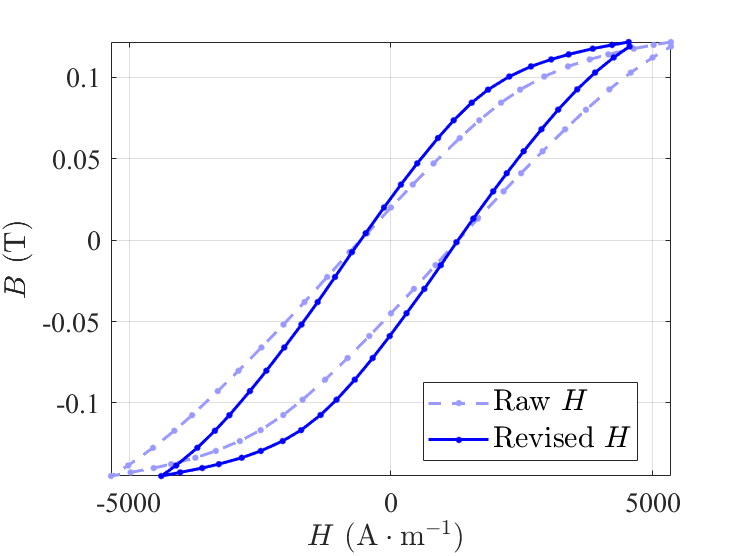


stc.label.x.String = '$H\ \mathrm{(A\cdot m^{-1})}$ ';
stc.label.y.String = '$B$ (T)';
stc.leg.String = ["Raw $H$"; "Revised $H$"];

%MyExport_pdf


fit_H_re_1 = Fit_HAndB(H_re(1:27), B(1:27))

fit_H_re_1 =      常规模型:
     fit_H_re_1(x) = a*atan(b*x+c)+d
     系数(置信边界为 95%):
       a =      0.1413  (0.1318, 0.1507)
       b =   0.0003428  (0.0003081, 0.0003775)
       c =      0.4132  (0.3717, 0.4546)
       d =    -0.02757  (-0.03276, -0.02238)

fit_H_re_2 = Fit_HAndB(H_re(27:end), B(27:end))

fit_H_re_2 =      常规模型:
     fit_H_re_2(x) = a*atan(b*x+c)+d
     系数(置信边界为 95%):
       a =      0.1394  (0.1303, 0.1484)
       b =   0.0003461  (0.0003122, 0.0003799)
       c =     -0.4797  (-0.5228, -0.4367)
       d =     0.00298  (-0.001997, 0.007957)


fit_H_1 = Fit_HAndB(H(1:27), B(1:27))

fit_H_1 =      常规模型:
     fit_H_1(x) = a*atan(b*x+c)+d
     系数(置信边界为 95%):
       a =     -0.1533  (-0.1655, -0.141)
       b =  -0.0002411  (-0.0002682, -0.000214)
       c =      -0.342  (-0.3823, -0.3018)
       d =     -0.0285  (-0.03455, -0.02244)

fit_H_2 = Fit_HAndB(H(26:end), B(26:end))

fit_H_2 =      常规模型:
     fit_H_2(x) = a*atan(b*x+c)+d
     系数(置信边界为 95%):
       a =     -0.1491  (-0.1615, -0.1366)
       b =  -0.0002482  (-0.0002777, -0.0002187)
       c =      0.3584  (0.3144, 0.4023)
       d =    0.004164  (-0.002296, 0.01062)

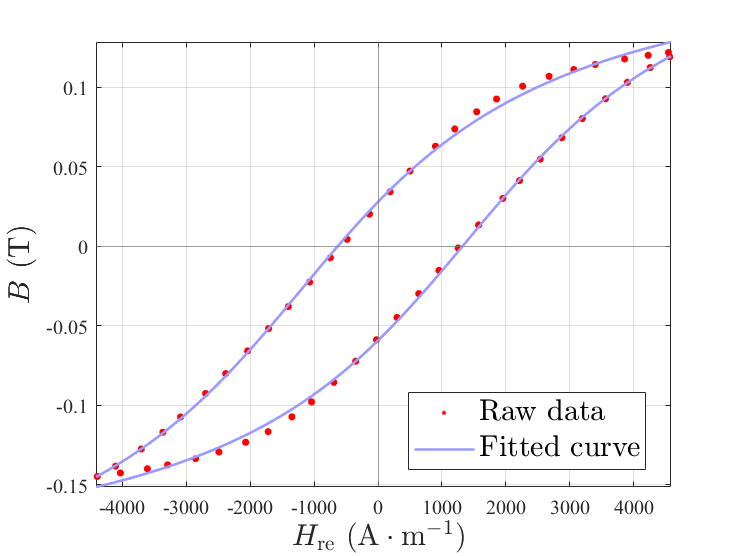


figure('Color', [1 1 1])
ax = axes;
sca = MyScatter_ax(ax, H_re, B);
sca.scatter.scatter_1.SizeData = 150;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';

x_array = linspace(H_re(27)-20, H_re(end)+20, 100);
p1 = MyPlot_ax(ax, x_array, fit_H_re_1(x_array)');
p2 = MyPlot_ax(ax, x_array, fit_H_re_2(x_array)');

xline(0, 'Color', [0.5, 0.5, 0.5])
yline(0, 'Color', [0.5, 0.5, 0.5])

p1.plot.plot_1.LineWidth = 1.3;
p2.plot.plot_1.LineWidth = 1.3;
p1.label.x.String = '$H_{\mathrm{re}}\ \mathrm{(A\cdot m^{-1})}$ ';
p1.label.y.String = '$B$ (T)';
p1.leg.String = ["Raw data"; "Fitted curve"];

%MyExport_pdf

MyPrint_xlsx([H', H_re'], 3)

ans = 53×2 cell 数组
    {'5351.667' }    {'4543.955' }
    {'5022.500' }    {'4226.725' }
    {'4638.333' }    {'3857.811' }
    {'4155.000' }    {'3397.688' }
    {'3800.000' }    {'3063.245' }
    {'3385.000' }    {'2676.761' }
    {'2929.167' }    {'2262.042' }
    {'2468.333' }    {'1854.924' }
    {'2104.167' }    {'1543.809' }
    {'1689.167' }    {'1200.428' }
    {'1315.000' }    {'898.545'  }
    {'814.167'  }    {'501.162'  }
    {'417.500'  }    {'190.704'  }
    {'0.000'    }    {'-133.292' }
    {'-454.167' }    {'-482.682' }
    {'-792.500' }    {'-744.090' }
    {'-1220.000'}    {'-1070.129'}
    {'-1653.333'}    {'-1401.338'}
    {'-2054.167'}    {'-1710.657'}
    {'-2476.667'}    {'-2039.654'}
    {'-2914.167'}    {'-2382.324'}
    {'-3310.833'}    {'-2696.097'}
    {'-3801.667'}    {'-3088.785'}
    {'-4142.500'}    {'-3365.957'}
    {'-4549.167'}    {'-3702.993'}
    {'-5023.333'}    {'-4105.540'}
    {'-5352.500'}    {'-4391.602'}
    {'-4975.833'}    {'-4029.525'}
 